Consider a small distribution system, as shown in the single line diagram of **Figure**. The distribution substation may be operated with only one rather than two power transformer for certain operating conditions. Assume the high voltage bus of the power transformer is connected to a very strong power system that can be considered as an infinite bus. The protection system for **three-phase faults**is to be designed. The relevant data is shown the **Figure**, and the transformer reactances are in Ohms referred to the 24 kV side. 

(a) Neglect resistance, consider a bolted (*Zf* = 0Ω ) fault and calculate the minimum and maximum fault currents (Amps) for a fault at bus 4.

(b) Neglect resistance, consider a resistive fault of R*f* = 1 W and calculate the minimum and maximum fault currents (Amps) for a fault at bus `n`.

                              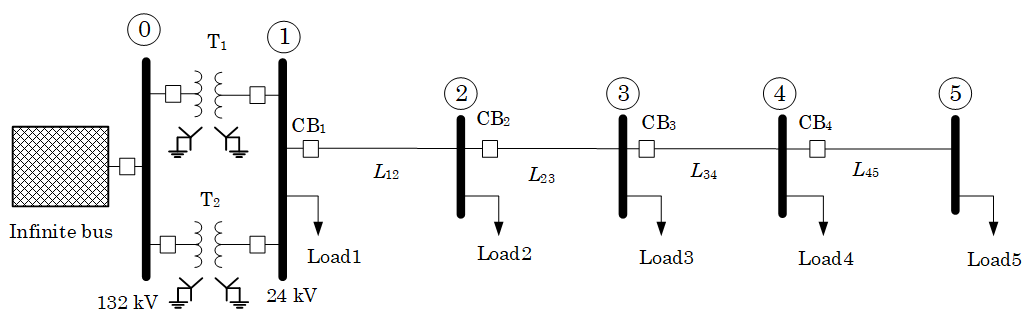

**Figure. Transformer (T1****= T****2****): 50 MVA, 132 kV/24kV, Ynyn, *****X******T***** = 0.3456**Ω**. Lines length: *****L*****12**** = 12 km, *****L*****23****= 8 km, *****L*****34**** = 1 km, *****L*****45**** = 2 km, *****X******L*****= 0.812**Ω**/km. **

clc
clear
XT = 0.3456

XT = 0.3456

XL12 = 12 *0.812

XL12 = 9.7440

XL23 = 8 * 0.812

XL23 = 6.4960

XL34 = 1 * 0.812

XL34 = 0.8120

XL45 = 2 * 0.812

XL45 = 1.6240

VLN = 24000/sqrt(3);    % VLN: Line to neutral rated voltage, in Volts
Rf = 1;                 % Rf: Fault resistance at 5, in Ohms

*Maximum fault current* will occur for a three-phase fault with **both transformers in service**. 

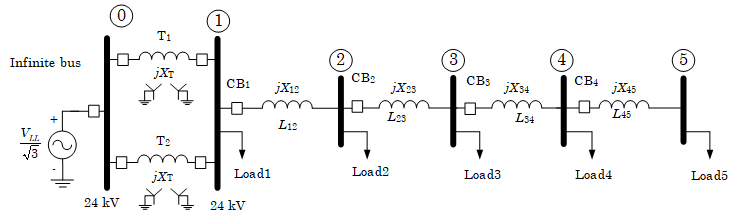

*Minimum fault current* will occur with **only one transformer in service for a line to line fault**.

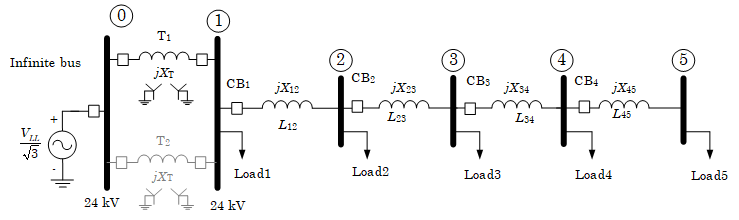

*Maximum fault current* at 4 is produced by the *minumum impedance*, two transformers in parallel

XT1 = (XT/2 + XL12 + XL23 + XL34)*i;
fprintf(' Z4mim = (%5.5f + j%5.5f)Ω = (%5.5f ∠ %5.5f°)Ω',real(XT1),imag(XT1),abs(XT1),angle(XT1)*180/pi)

 Z4mim = (0.00000 + j17.22480)Ω = (17.22480 ∠ 90.00000°)Ω

*Mimimum fault *current at 4 is produced by the *maximum impedance*, one transformer

XT2 = (XT + XL12 + XL23 + XL34)*i;
fprintf(' Z4max = (%5.5f + j%5.5f)Ω = (%5.5f ∠ %5.5f°)Ω',real(XT2),imag(XT2),abs(XT2),angle(XT2)*180/pi)

 Z4max = (0.00000 + j17.39760)Ω = (17.39760 ∠ 90.00000°)Ω

Fault current at 4:

Maximum fault current using Ohms Law (IL4max):

IL4max = VLN/XT1;
fprintf(' IL4,max = (%5.5f + j%5.5f)A = (%5.5f ∠ %5.5f°)A',real(IL4max),imag(IL4max),abs(IL4max),angle(IL4max)*180/pi)

 IL4,max = (0.00000 + j-804.44513)A = (804.44513 ∠ -90.00000°)A

Minimum fault current using Ohms Law (IL4min):

IL4min = VLN/XT2;
fprintf(' IL4,min = (%5.5f + j%5.5f)A = (%5.5f ∠ %5.5f°)A',real(IL4min),imag(IL4min),abs(IL4min),angle(IL4min)*180/pi)

 IL4,min = (0.00000 + j-796.45505)A = (796.45505 ∠ -90.00000°)A

Now considering tha fault at the tail of the feeder, node 5, and fault resistance Rf = 1Ω

Rf = 1;

*Maximum fault *current at 5 is produced by the* minumum impedance*, two transformers in parallel

ZT1 = ((XT/2 + XL12 + XL23 + XL34 +XL45)*i + Rf);
fprintf(' Z5mim = (%5.5f + j%5.5f)Ω = (%5.5f ∠ %5.5f°)Ω',real(ZT1),imag(ZT1),abs(ZT1),angle(ZT1)*180/pi)

 Z5mim = (1.00000 + j18.84880)Ω = (18.87531 ∠ 86.96309°)Ω

*Mimimum fault current *at 4 is produced by the *maximum impedance*, one transformer

ZT2 = ((XT + XL12 + XL23 + XL34 + XL45)*i + Rf);
fprintf(' Z5max = (%5.5f + j%5.5f)Ω = (%5.5f ∠ %5.5f°)Ω',real(ZT2),imag(ZT2),abs(ZT2),angle(ZT2)*180/pi)

 Z5max = (1.00000 + j19.02160)Ω = (19.04787 ∠ 86.99063°)Ω

Fault current at 5:

Maximum fault current using Ohms Law (IL5max):

IL5max = VLN/ZT1;
fprintf(' IL5,max = (%5.5f + j%5.5f)A = (%5.5f ∠ %5.5f°)A',real(IL5max),imag(IL5max),abs(IL5max),angle(IL5max)*180/pi)

 IL5,max = (38.89220 + j-733.07130)A = (734.10226 ∠ -86.96309°)A

Minimum fault current using Ohms Law (IL5min):

IL5min = VLN/ZT2;
fprintf(' IL5,min = (%5.5f + j%5.5f)A = (%5.5f ∠ %5.5f°)A',real(IL5min),imag(IL5min),abs(IL5min),angle(IL5min)*180/pi)

 IL5,min = (38.19072 + j-726.44866)A = (727.45184 ∠ -86.99063°)A